# AC signals

## Sinusoidal function

AC signals in steady-state circuits, such as voltage and current are described by pure sinusoidal functions.

A sinusoidal function is defined by:

- *YA*: the amplitude of the sinusoid

- *ω*: the angular frequency [rad/s]

- *φ*: the phase [rad]

The period *T*, is defined as: 

The frequency *f* (in Hz), is defined as:

### Effective value (RMS)   

The effective or RMS (Root Mean Square) value of any periodic current (or signal) is equal to the **value of the direct current that would produce the same average power **dissipation in a resistive load. 

- This value is useful for power calculation in AC.

- Its calculation comes from Joule’s law, $p\left(t\right)=R\;i^2 \left(t\right)$.

- If the signal is a pure sinusoidal, the relationships between amplitudes and RMS are fixed and known: 


$$V_{\textrm{PK}\left(\textrm{peak}\right)} =\sqrt{2}\;V_{\textrm{RMS}}$$



$$V_{\textrm{PP}\left(\textrm{peak}-\textrm{to}-\textrm{peak}\right)} =2\sqrt{2}\;V_{\textrm{RMS}}$$


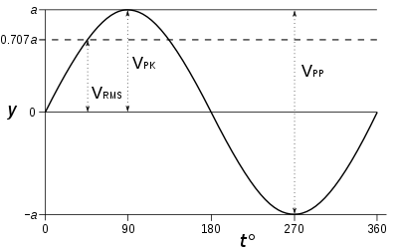

## Exercise 1: AC signal parameters 

Given the sinusoidal signal, calculate its:

- Amplitude

- Phase

- Angular frequency

- Period

- Frequency

- RMS value

**Solution:**

disp('Solution:')

Solution:


A=10

A = 10

phi=pi/2

phi = 1.5708

omega=4*pi

omega = 12.5664

T=2*pi/omega

T = 0.5000

f=1/T

f = 2

RMS=A/sqrt(2)

RMS = 7.0711

Representation:

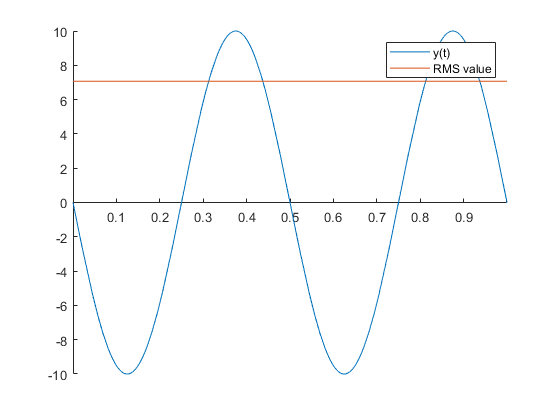

fplot(@(x) 10*cos((4*pi*x)+(pi/2)), [0 1])
hold on
fplot(RMS, [0 1])
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
box off

legend('y(t)','RMS value')

## Exercise 2: AC graph

Given the plotted voltage and current signals, find their sinusoidal expresions.

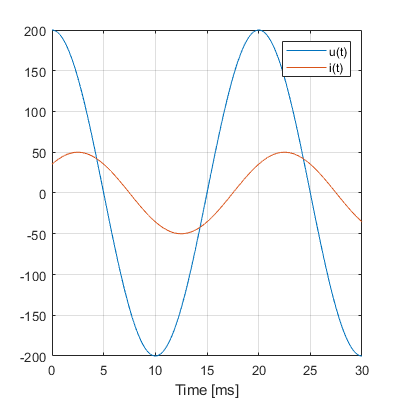

**Solution:**


$$u\left(t\right)=200\;\cos \left(100\pi \;t\right)\;\left\lbrack V\right\rbrack$$



$$i\left(t\right)=50\;\cos \left(100\pi \;t-\frac{\pi }{4}\right)\left\lbrack A\right\rbrack$$


**Resolution:**

% Amplitude
Ua=200

Ua = 200

Ia=50

Ia = 50

% Frequency
T=20e-3 % in [s] from the graph

T = 0.0200

f=1/T

f = 50

omega=2*pi*f

omega = 314.1593

To calculate the phase, we observe the time where the maximum is reached for each signal.

The maximum or amplitude is reached when the $\cos \left(\omega t+\phi \right)=1$, hence $\omega t+\phi =0$.

% Phase
tu=0  % t when u(t) reaches maximum

tu = 0

Uang=0-omega*tu

Uang = 0

ti=2.5*10e-3  % t when i(t) reaches maximum

ti = 0.0250

Iang=0-omega*ti

Iang = -7.8540